% Kym Derriman (Partner: Evan Howell)
% Lab 6: Damped Harmonic Motion
% 10/17/2024

% -------------------------------------
% Spring Force vs Displacement Analysis
% -------------------------------------


% -----------------------------------------
% Import Measured Data weights = (0 - 100g)
% -----------------------------------------

% Preallocation and setup
num_measurements = 6;
position_means = zeros(1, num_measurements);
position_std_deviations = zeros(1, num_measurements);
position_std_err_mean = zeros(1, num_measurements);
filename.Temp = "S4L6_%d.txt";

% Loop to import and process data
for i = 1:num_measurements
    % Read data from corresponding file
    data = readtable(sprintf(filename.Temp, i));
    current_position = data.Position;
    N = length(current_position);
    position_means(i) = mean(current_position);
    position_std_deviations(i) = std(current_position);
    position_std_err_mean(i) = position_std_deviations(i)/sqrt(N);
end

% Convert position data to displacement by subtracting measured values of x - x_0. 
% I did this because I was getting a negative slope (negative B value, which was giving 
% me a complex number for my theoretical calculation of period in step 12.

% Extract x_0 from position means
x0 = position_means(1);

% Calculate and create displacement array
displacement_array = x0 - position_means;

% Mass of weights in kg (from stamps on weights)
mass_weights = [0.0, 0.1, 0.2, 0.3, 0.4, 0.5];

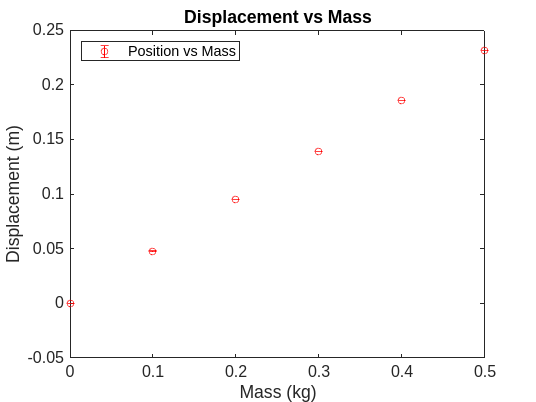

% -------------------------------
% Plot: Displacement vs. Mass
% -------------------------------

figure; grid on; box on;

% Plot Position with error bars
errorbar(mass_weights, displacement_array, position_std_err_mean, ...
    'ro', 'MarkerSize',5, 'DisplayName','Position vs Mass');

% Title and Labels with Uncertainties
title('Displacement vs Mass', 'FontSize', 14);
xlabel('Mass (kg)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);
legend('Location','northwest');
set(gca, 'FontSize', 12);

% -----------------------------------
% Linear Fit for Spring Constant (k)
% -----------------------------------

% Performs a least-squares fit to the data, assuming a linear relationship between 
% the mass of the weights and the displacement according to Hooke's Law (F = -k*x)

% A = y-intercept of the fit, B = slope, related to spring constant k
% sigA and sigB are uncertainties in A, B weights = 1 / (std err mean)^2
[A, B, sigma_A, sigma_B] = lsqFit(mass_weights, ...
    displacement_array, 1 ./((position_std_err_mean).^2));

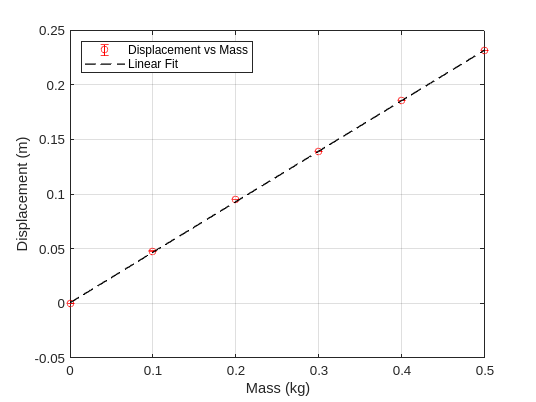

% Plot Linear Fit
figure; grid on; box on; hold on;

errorbar(mass_weights, displacement_array, position_std_err_mean, ...
    'ro', 'MarkerSize',5, 'DisplayName','Position vs Mass');

x_fit = linspace(min(mass_weights), max(mass_weights), 100);
y_fit = B * x_fit + A;
plot(x_fit, y_fit, 'k--', 'LineWidth', 1)
xlabel('Mass (kg)', 'FontSize', 11);
ylabel('Displacement (m)', 'FontSize', 11);

% Legend to show both the data and the fit
legend({'Displacement vs Mass', 'Linear Fit'}, 'Location', 'northwest');

% Set x-axis limits to only plot the data within the range
xlim([min(mass_weights), max(mass_weights)]);

hold off;

% -----------------------------------
% Calculation of Spring Constant (k)
% -----------------------------------

g = 9.81; % Acceleration due to gravity in m/s^2
k = g / B;
sig_k = (g * sigma_B) / (B^2);

fprintf('Parameters and Uncertainties y = Bx + A:\n');

Parameters and Uncertainties y = Bx + A:


fprintf('-------------------------------------------');

-------------------------------------------

fprintf('Intercept (A) = %.4f ± %.4f m\n', A, sigma_A);

Intercept (A) = 0.0005 ± 0.0000 m


fprintf('Slope (B) = %.4f ± %.4f m/kg\n', B, sigma_B);

Slope (B) = 0.4626 ± 0.0001 m/kg


fprintf('Spring constant (k) = %.2f ± %.2f N/m\n', k, sig_k);

Spring constant (k) = 21.21 ± 0.00 N/m


fprintf('-------------------------------------------');

-------------------------------------------

% ----------------------------------------------
% Import and Prepare Measured Data weight = 500g
% ----------------------------------------------

% Data from oscillating spring with 500g weight attached.

tbl = readtable("L6_500g_Oscillation.txt");
times = tbl.Time;
positions = tbl.Position;
velocities = tbl.Velocity;
accelerations = tbl.Acceleration;

% Prepare data to plot oscillation about zero.

% Calculate the means 
position_means = mean(positions);
vel_means = mean(velocities);
accel_means = mean(accelerations);

% Shift plots down by subtracting means from measured values.
shifted_positions = positions - position_means;
shifted_velocities = velocities - vel_means;
shifted_accelerations = accelerations - accel_means;

% Convert position data to displacement data
x0 = shifted_positions(1);
displacements = x0 - shifted_positions;

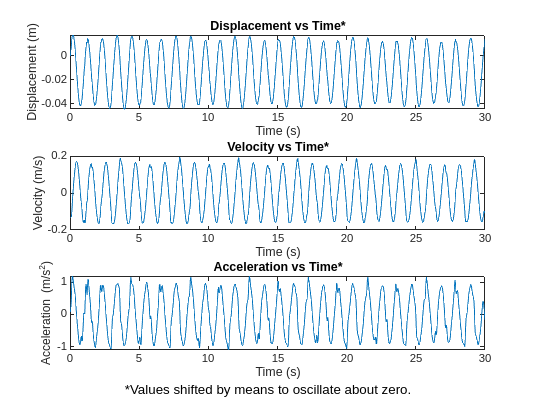

% --------------------------------------------------
% Plot Displacement, Velocity, Acceleration Data
% --------------------------------------------------

figure;

% Subplot 1: Displacements (shifted)
subplot(3, 1, 1); plot(times, displacements);
title('Displacement vs Time*'); xlabel('Time (s)'); ylabel('Displacement (m)');

% Subplot 2: Velocities (shifted)
subplot(3, 1, 2); plot(times, shifted_velocities);
title('Velocity vs Time*'); xlabel('Time (s)'); ylabel('Velocity (m/s)');

% Subplot 3: Accelerations (shifted)
subplot(3, 1, 3); plot(times, shifted_accelerations);
title('Acceleration vs Time*'); xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');

% Add annotation to indicate the asterisk explanation
annotation('textbox', [0.1, 0.01, 0.8, 0.05], 'String', ...
    '*Values shifted by means to oscillate about zero.','EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', 'FontSize', 10);

% -----------------------------------------------------------------
% Find Zero-crossing Times for Displacement, Velocity, Acceleration
% -----------------------------------------------------------------

% Threshold values
trs_displacement = 0.0023;
trs_velocity = 0.017;
trs_accel = 0.12;

% Absolute value < trs implies zero-crossing
zero_cross_displacement = times(abs(displacements) < trs_displacement);
zero_cross_velocity = times(abs(shifted_velocities) < trs_velocity);
zero_cross_accel = times(abs(shifted_accelerations) < trs_accel);

% Set weights of 1/30 to zero-crossings in least-squares fit.
w_displacement = ones(length(zero_cross_displacement), 1)*(1/30);
w_velocity = ones(length(zero_cross_velocity), 1)*(1/30);
w_acceleration = ones(length(zero_cross_accel), 1)*(1/30);

% Least-squares fit: A = y-intercept, B = time between zero-crossings
[A_disp, B_disp, sigma_A_disp, sigma_B_disp] = lsqFit( ...
    1:length(zero_cross_displacement), zero_cross_displacement, w_displacement);
[A_vel, B_vel, sigma_A_vel, sigma_B_vel] = lsqFit( ...
    1:length(zero_cross_velocity), zero_cross_velocity, w_velocity);
[A_accel, B_accel, sigma_A_accel, sigma_B_accel] = lsqFit( ...
    1:length(zero_cross_accel), zero_cross_accel, w_acceleration);


% --------------------------------------------------
% Extract T of Position, Velocity, and Acceleration
% --------------------------------------------------

% Extract value of T
T_displacement = 2 * B_disp; % Displacement
T_velocity = 2 * B_vel; % Velocity
T_acceleration = 2 * B_accel; % Acceleration

% Calculate uncertainties in T
sigma_T_disp = 2 * sigma_B_disp;
sigma_T_vel = 2 * sigma_B_vel;
sigma_T_accel = 2 * sigma_B_accel;

% To calculate theoretical value of T, we need the mass of the weight,
% the mass of the weight holder, and the effective mass of the spring.

% Mass of weight holder, weight, and spring (1/3 * spring mass), g to kg
mass_holder = 99.1/1000;
mass_weight = 500/1000;
mass_spring_eff = 29.2/1000;

% Total mass for theoretical T calculation
total_mass = mass_holder + mass_spring_eff + mass_weight;

% Calculate theoretical value of T with T = 2*pi*sqrt(m/k) where m is
% the mass of the weight, the weight holder and the spring weight.
T_theoretical = 2*pi*sqrt(total_mass/k);


% Data for periods and uncertainties
T_values = [T_displacement, T_velocity, T_acceleration];
sigma_T_values = [sigma_T_disp, sigma_T_vel, sigma_T_accel];
labels = {'Displacement', 'Velocity', 'Acceleration'};

% Loop through and print each result
for i = 1:length(T_values)
    fprintf('%s Data:\n', labels{i});
    fprintf('Measured period (T): %.4f s ± %.4f s\n', T_values(i), sigma_T_values(i));
end

Displacement Data:


Measured period (T): 1.0475 s ± 0.0882 s


Velocity Data:


Measured period (T): 0.9646 s ± 0.0817 s


Acceleration Data:


Measured period (T): 0.8537 s ± 0.0634 s


fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Theoretical period (T_theoretical): %.4f s\n', T_theoretical);

Theoretical period (T_theoretical): 1.0815 s


fprintf('--------------------------------------------------\n');

--------------------------------------------------
